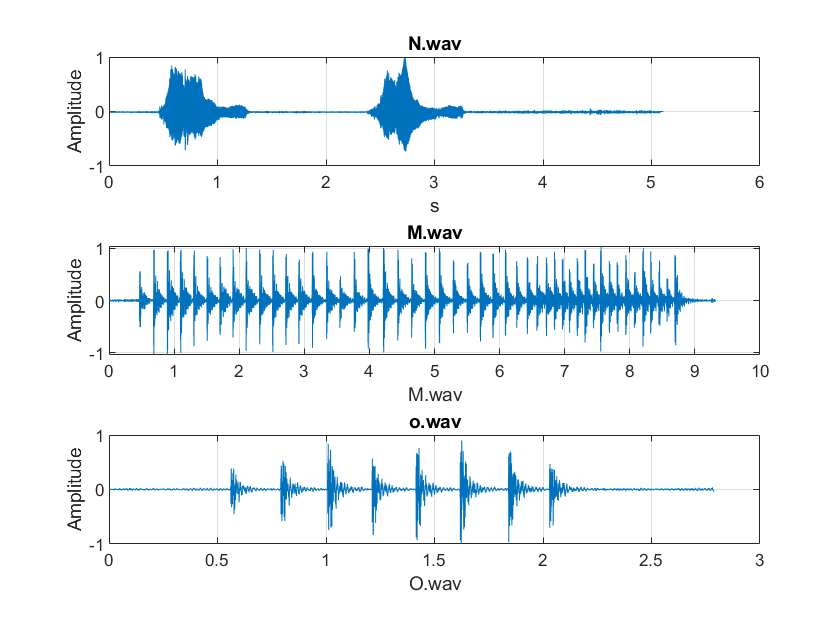

figure(1);

[x,Fs]=audioread('meow.wav');

x=x(:,1);
dt1=1/Fs; %sampling interval
t1=0:dt1:(length(x)*dt1)-dt1; % time vector

subplot(3,1,1);
plot(t1,x);
xlabel('s');
ylabel('Amplitude');
title('N.wav')
grid on;


[y,Fs]=audioread('M.wav');

y=y(:,1);
dt2=1/Fs;
t2=0:dt2 :(length(y)*dt2)-dt2;

subplot(3,1,2);
plot(t2,y); 
xlabel('M.wav');
ylabel('Amplitude');
title('M.wav')
grid on;

[z,Fs]= audioread('O.wav');

z=z(:,1);
dt3=1/Fs;
t3=0:dt3:(length(z)*dt3)-dt3;
subplot(3,1,3);
plot(t3,z); 
xlabel('O.wav');
ylabel('Amplitude');
title('o.wav')
grid on;

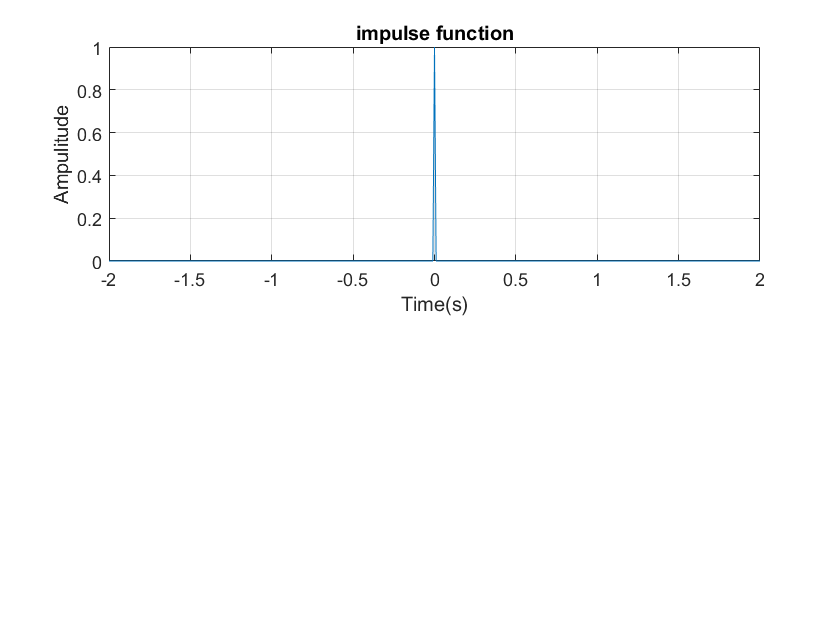


figure

ts=(-2:0.01:2);
impulse=ts==0;
unitstep=ts>=0;

subplot(211)
plot(ts,impulse);
xlabel('Time(s)');
ylabel('Ampulitude');
title('impulse function');
grid on;

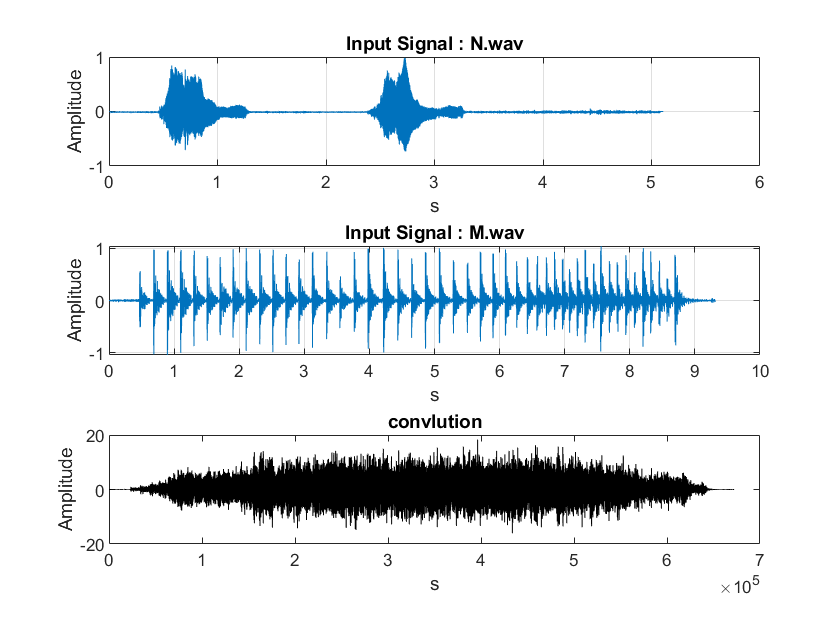



figure

subplot(3,1,1);
plot(t1,x);
xlabel('s');
ylabel('Amplitude');
title('Input Signal : N.wav');
grid on;


subplot(3,1,2);
plot(t2,y);
xlabel('s');
ylabel('Amplitude');
title('Input Signal : M.wav');
grid on;

subplot(3,1,3);
op=conv2(x,y);
plot(op,'k');

title('convlution');
xlabel('s');
ylabel('Amplitude');